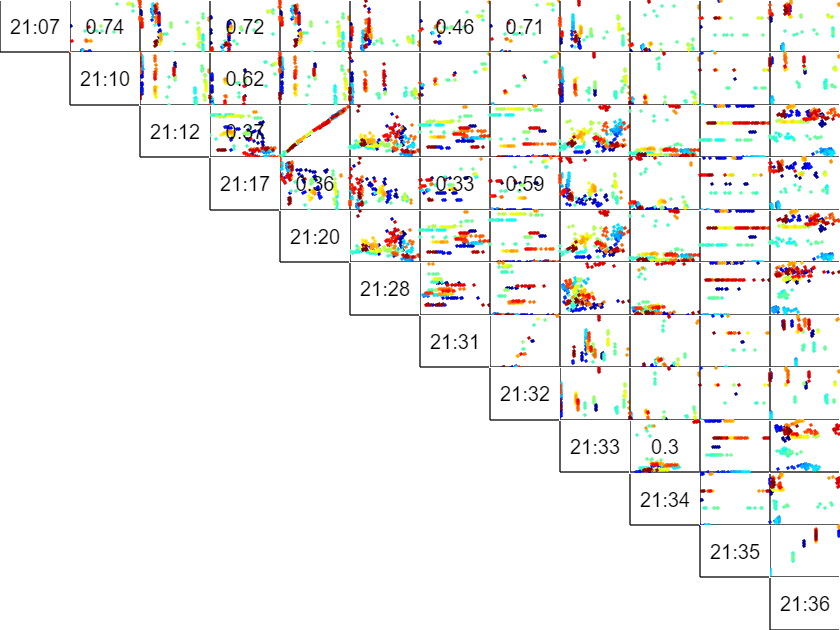

Features = DFD_FeatureTable_TimeDomain;
SignalNames = signalNames_Time;
FeatureNames = featureNames_Time;
lowerR2 = 0.3;
upperR2 = 0.8;
r2ReducedThreshold = 0.9;
selectedFeature = 7; % RMS
saveFigures = true;
R2 = fnPlotSignalVsSignal(Features, lowerR2, upperR2, selectedFeature, FeatureNames, SignalNames, sensorNames);        

disp(num2str(R2, '%.2f  '));

0.00  0.74  0.29  0.72  0.29  0.01  0.46  0.71  0.01  0.00  0.00  0.00
0.00  0.00  0.18  0.62  0.18  0.00  0.81  1.00  0.00  0.04  0.00  0.01
0.00  0.00  0.00  0.37  1.00  0.03  0.01  0.17  0.11  0.00  0.17  0.12
0.00  0.00  0.00  0.00  0.36  0.00  0.33  0.59  0.09  0.02  0.07  0.03
0.00  0.00  0.00  0.00  0.00  0.04  0.02  0.17  0.11  0.00  0.16  0.12
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.05  0.28  0.30
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.82  0.06  0.10  0.02  0.00
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.01  0.05  0.00  0.01
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.30  0.08  0.03
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.01
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.91
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  1.00


selectedSignal = 1; % row 1
[selectedSignalArray, selectedSignalData, numOfSelectedSignals] = fnSelectSignals(...
    selectedSignal, selectedFeature, featureArray, R2, upperR2, lowerR2, r2ReducedThreshold, true);

Sig 2 Sig 8 = 1.00
     1     2     4     7     8

     1     2     4     7



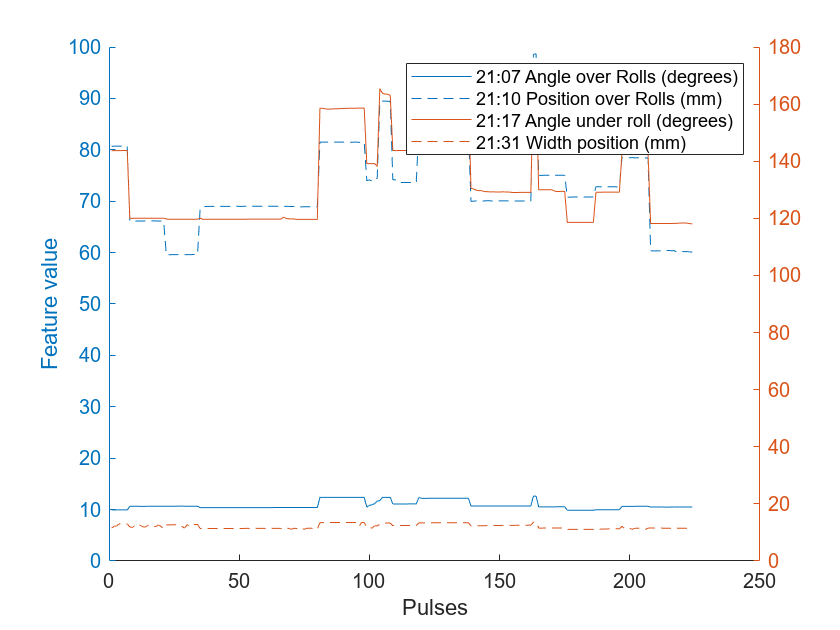

figure(); hold on;
FeatureNames(selectedFeature);%title(FeatureNames(selectedFeature));
xlabel("Pulses");
ylabel("Feature value");
secondaryAxisArrayIndex = [2 3];
for i = 1:numOfSelectedSignals
    if ismember(i, secondaryAxisArrayIndex)
        yyaxis right;
    else
        yyaxis left;
    end
    plot(selectedSignalData{i});
    leg{i} = char(sensorNames(selectedSignalArray(i)));
end
legend(leg);
if (saveFigures == true)
    filename = "..\Latex Document\figures\Models_Feature" + selectedFeature ...
        + "Signal" + selectedSignal;
    print(filename,'-depsc','-tiff')
end

txtTitle = "7 RMS"

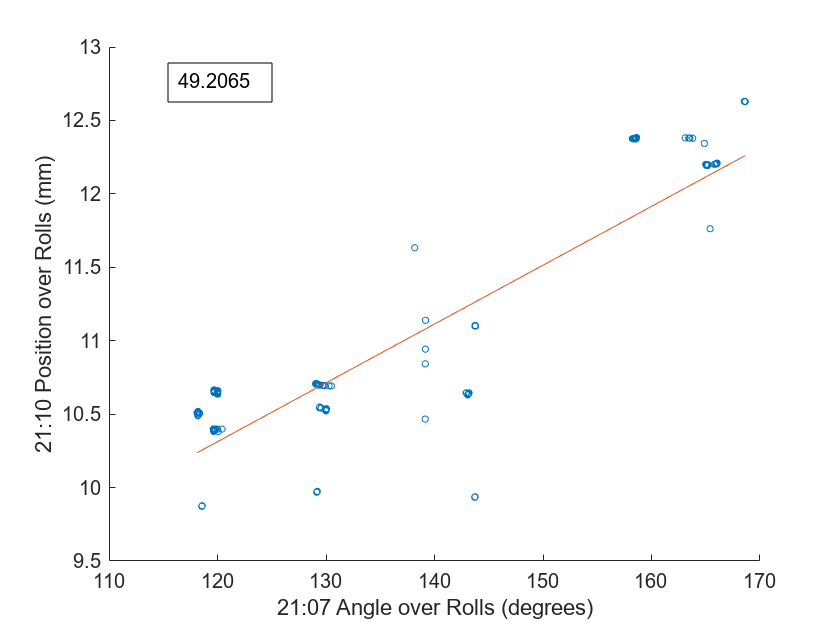

txtTitle = "7 RMS"

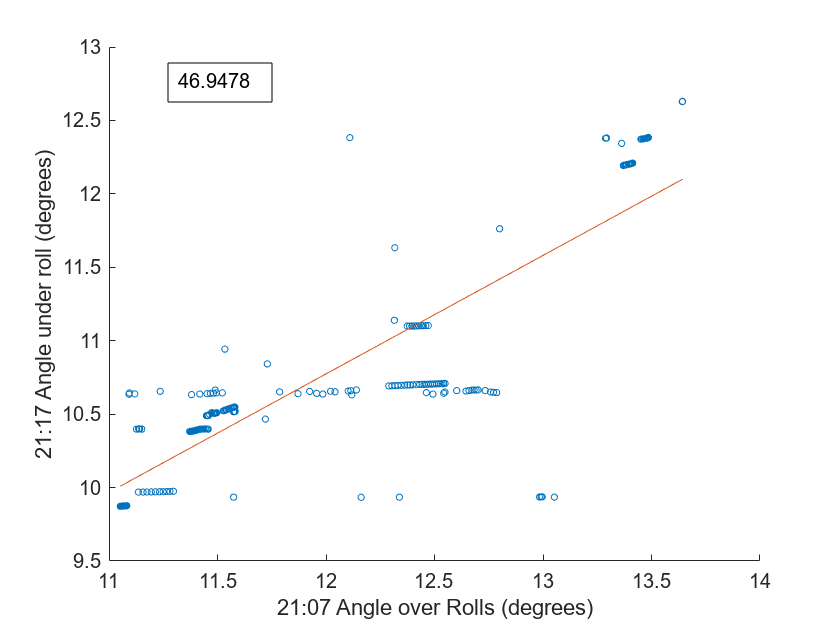

txtTitle = "7 RMS"

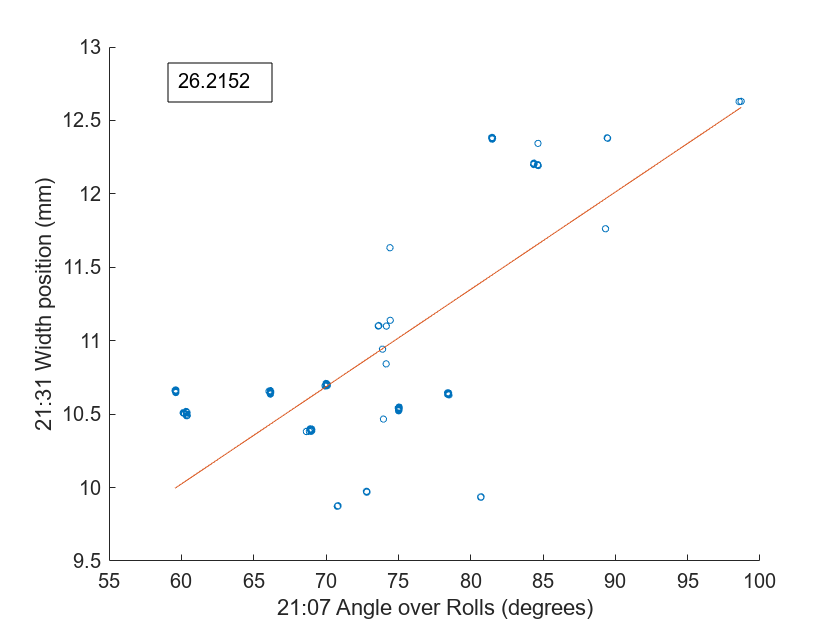

selectedSignalIdx = find(selectedSignalArray == selectedSignal);
selectedSignalIdx = find(selectedSignalArray == selectedSignal);
linearModelNum = 1;
for index = 1 : numOfSelectedSignals
    if selectedSignalArray(index) ~= selectedSignal
        fnPlotModel(selectedSignalData{selectedSignalIdx}, ...
            selectedSignalData{index}, ...
            FeatureNames_Combined(selectedFeature), ...
            sensorNames(selectedSignalArray(index)), ...
            sensorNames(selectedSignal));
        if (saveFigures == true)
            filename = "..\Latex Document\figures\Models_Feature" + selectedFeature ...
                + "Signal" + selectedSignal ...
                + "_Linear" + linearModelNum;
            export_fig(filename, '-eps', '-depsc');
            linearModelNum = linearModelNum + 1;
        end
    end
end

txtTitle = "RMS"

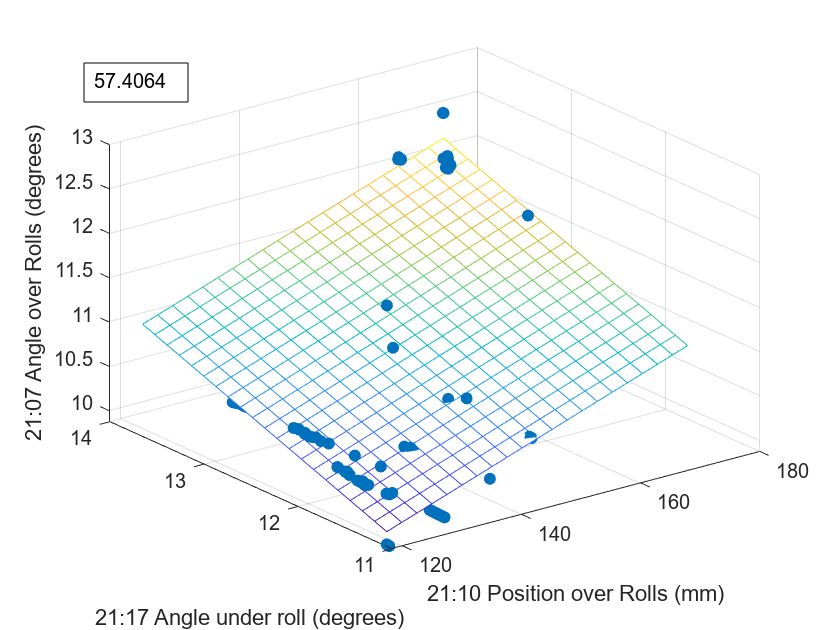

txtTitle = "RMS"

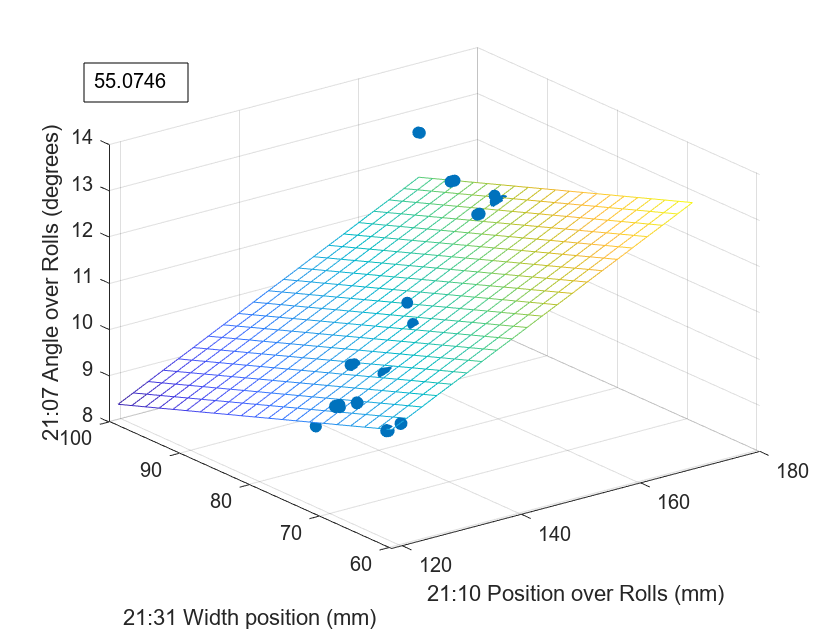

txtTitle = "RMS"

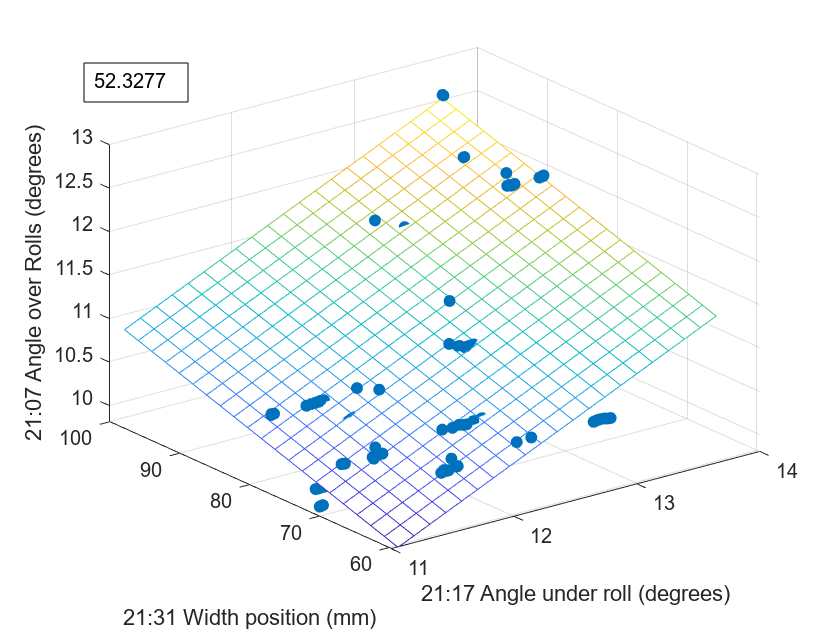

multivariateModelNum = 1;
if numOfSelectedSignals > 2
    for index1 = 1 : numOfSelectedSignals
        for index2 = index1+1 : numOfSelectedSignals
            if selectedSignalArray(index1) ~= selectedSignal && selectedSignalArray(index2) ~= selectedSignal 
                %fprintf("%i %i %i", selectedSignalIdx, index1, index2);
                Y_est = fnPlotModel3D( ...
                    selectedSignalData{selectedSignalIdx}, ...
                    selectedSignalData{index1}, ...
                    selectedSignalData{index2}, ...
                    FeatureNames(selectedFeature), ...
                    sensorNames(selectedSignalArray(selectedSignalIdx)), ...
                    sensorNames(selectedSignalArray(index1)), ...
                    sensorNames(selectedSignalArray(index2)));

                if (saveFigures == true)
                    filename = "..\Latex Document\figures\Models_Feature" + selectedFeature ...
                        + "Signal" + selectedSignal ...
                        + "_Multivariate" + multivariateModelNum;
                    export_fig(filename, '-eps', '-depsc');
                    multivariateModelNum = multivariateModelNum + 1;
                end
            end
        end
    end
end